# Demonstration of the approximation by B-spline curves

### Points for the approximation

P=[[0;0],[1;1],[3;1],[4;-1]]

P =      0     1     3     4
     0     1     1    -1


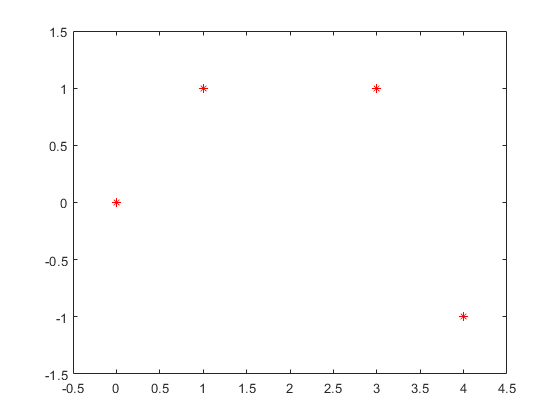

plot(P(1,:),P(2,:),'r*')
axis([-0.5 4.5 -1.5 1.5])

### Number of data

n=length(P)-1

n = 3

### Degree of the B-spline for linear spline

p=1

p = 1

### Number of knots

k=n+1-p

k = 3

### Knots

T=[zeros(1,p) 0:k k*ones(1,p)]

T =      0     0     1     2     3     3


### Number of knots, check the equality m=n+p+1.

m=length(T)-1

m = 5

### B-spline

B=B_spline(T,p);

### Points for drawing and counting the B-spline values

tt=linspace(0,k,101);
Bx=B_splval(B,P(1,:),tt);
By=B_splval(B,P(2,:),tt);

### B-spline is piecewise linear

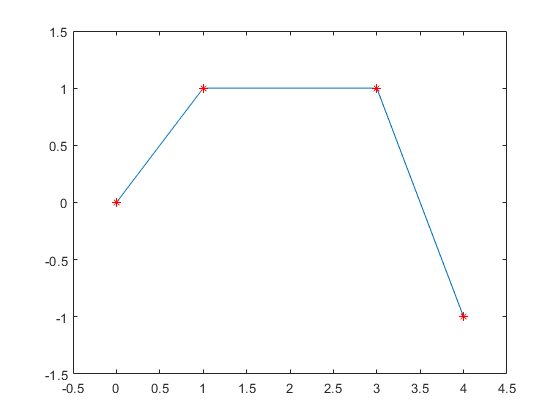

plot(Bx,By,P(1,:),P(2,:),'r*')
axis([-0.5 4.5 -1.5 1.5])

### Quadratic spline for the same data 

p=2;
k=n+1-p

k = 2

### Knots

T=[zeros(1,p) 0:k k*ones(1,p)]

T =      0     0     0     1     2     2     2


m=length(T)-1

m = 6

### B-spline

B=B_spline(T,p);
tt=linspace(0,k,101);
Bx=B_splval(B,P(1,:),tt);
By=B_splval(B,P(2,:),tt);

### B-spline is piecewise quadratic

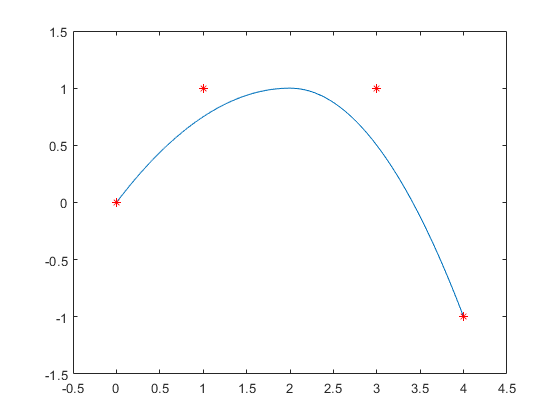

plot(Bx,By,P(1,:),P(2,:),'r*')
axis([-0.5 4.5 -1.5 1.5])

### Cubic spline for the same data 

p=3;
k=n+1-p

k = 1

### Knots

T=[zeros(1,p) 0:k k*ones(1,p)]

T =      0     0     0     0     1     1     1     1


m=length(T)-1

m = 7

### The knots indicate that the B-spline is the Bezier curve, in fact.

### B-spline

B=B_spline(T,p);
tt=linspace(0,k,101);
Bx=B_splval(B,P(1,:),tt);
By=B_splval(B,P(2,:),tt);

### B-spline is piecewise quadratic

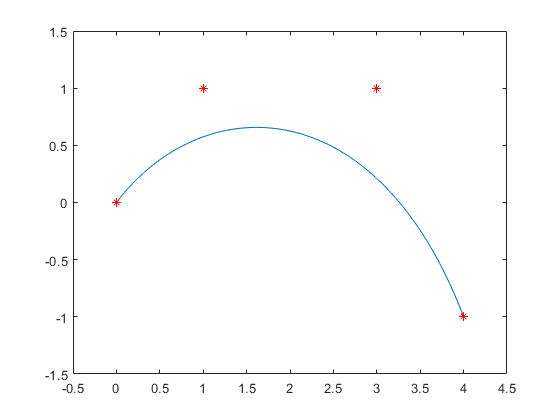

plot(Bx,By,P(1,:),P(2,:),'r*')
axis([-0.5 4.5 -1.5 1.5])

### New data, B-splies of all degrees

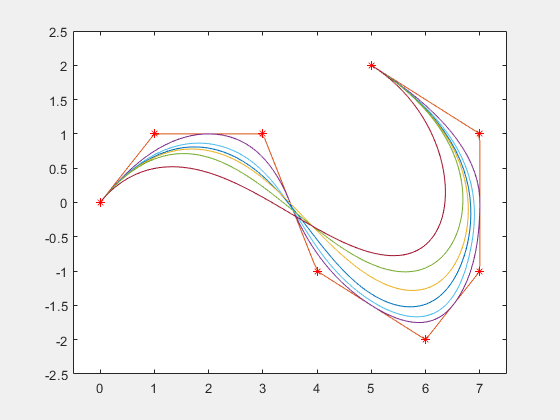

figure('visible','on')
P=[[0;0],[1;1],[3;1],[4;-1],[6;-2],[7;-1],[7;1],[5;2]];
plot(P(1,:),P(2,:),'r*')
axis([-0.5 7.5 -2.5 2.5])
hold on

n=length(P)-1;

for p=1:n
    k=n+1-p;
    T=[zeros(1,p) 0:k k*ones(1,p)];
    B=B_spline(T,p);
    tt=linspace(0,k,101);
    Bx=B_splval(B,P(1,:),tt);
    By=B_splval(B,P(2,:),tt);
    plot(Bx,By,P(1,:),P(2,:),'r*')
    axis([-0.5 7.5 -2.5 2.5])
    pause(1)
end